%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'tb_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_mtb_orthologs.xlsx';
trainingData = 'nature_ecoli';
standardize = '';

summaryTable = 1×11 table
      min       median      max      range      mean       std      interactionCount    synergyCount    antagonismCount    rejectNormality    pNormality
    _______    ________    ______    ______    _______    ______    ________________    ____________    _______________    _______________    __________

    -0.7394    0.039423    1.8743    2.6137    0.14977    0.5261           80                20               31                true           0.013901 


drugList = 11×1 cell array
    {0×0 char}
    {'CHL'   }
    {'CIP'   }
    {'ERY'   }
    {'FOX'   }
    {'FUS'   }
    {'PHL'   }
    {'RIF'   }
    {'SMX'   }
    {'TET'   }
    {'TMP'   }


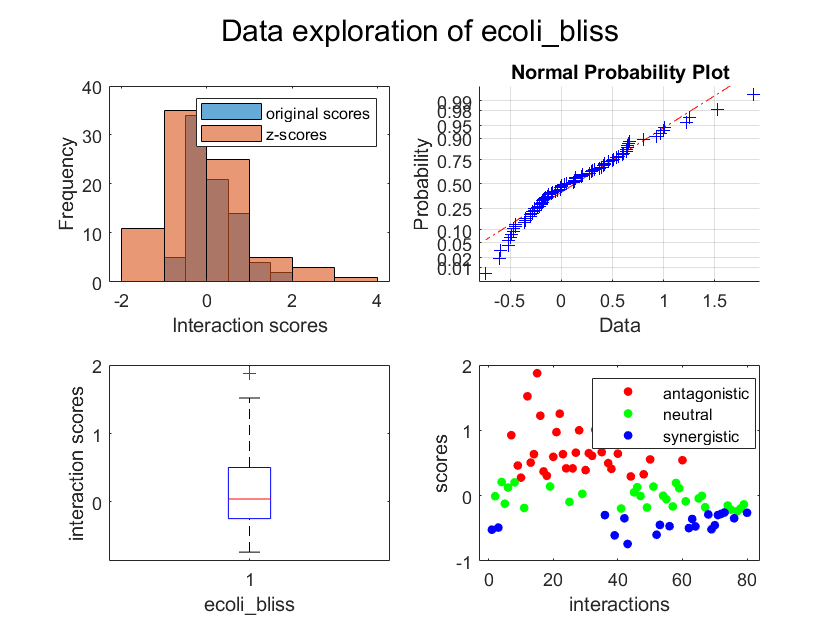

[summary,drugList] = dataExplore(testFile);

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,standardize);

Run 1
Elapsed time is 11.758850 seconds.
Run 2
Elapsed time is 11.633349 seconds.
Run 3
Elapsed time is 11.640427 seconds.
Run 4
Elapsed time is 14.230789 seconds.
Run 5
Elapsed time is 10.959948 seconds.


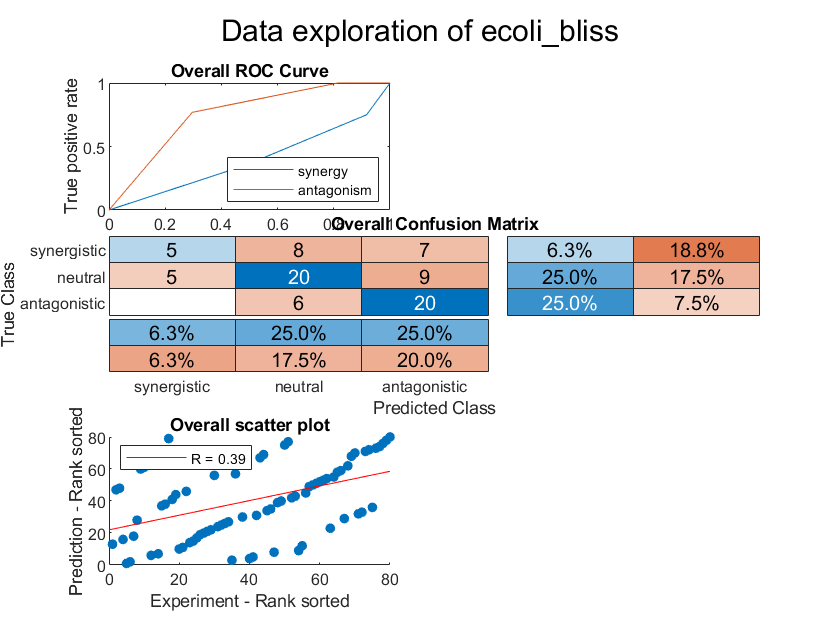

resultsTable = 5×13 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    ________________

averagesTable = 13×1 table
                                 Value 
                                _______

    Interactions                     16
    R (rank)                    0.43647
    P value                     0.24252
    Accuracy                     0.5625
    Absolute error                0.525
    Precision (synergy)         0.46667
    Recall (synergy)                NaN
    Precision (antagonism)      0.55738
    Recall (antagonism)         0.76905
    Mean Guess Error            -0.5625
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)             NaN
    AUC - ROC (antagonism)      0.76222


overviewTable = 13×1 table
                                 Value  
                                ________

    Interactions                      80
    R (rank)                     0.39258
    P value                     0.000316
    Accuracy                      0.5625
    Absolute error                 0.525
    Precision (synergy)              0.5
    Recall (synergy)                0.25
    Precision (antagonism)       0.55556
    Recall (antagonism)          0.76923
    Mean Guess Error             -0.5625
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.39583
    AUC - ROC (antagonism)       0.75783


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'ecoli_bliss.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'nature_ecoli';
standardize = 'standardized';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 10.884740 seconds.
Run 2
Elapsed time is 11.734365 seconds.
Run 3
Elapsed time is 10.795767 seconds.
Run 4
Elapsed time is 20.985469 seconds.
Run 5
Elapsed time is 22.093443 seconds.


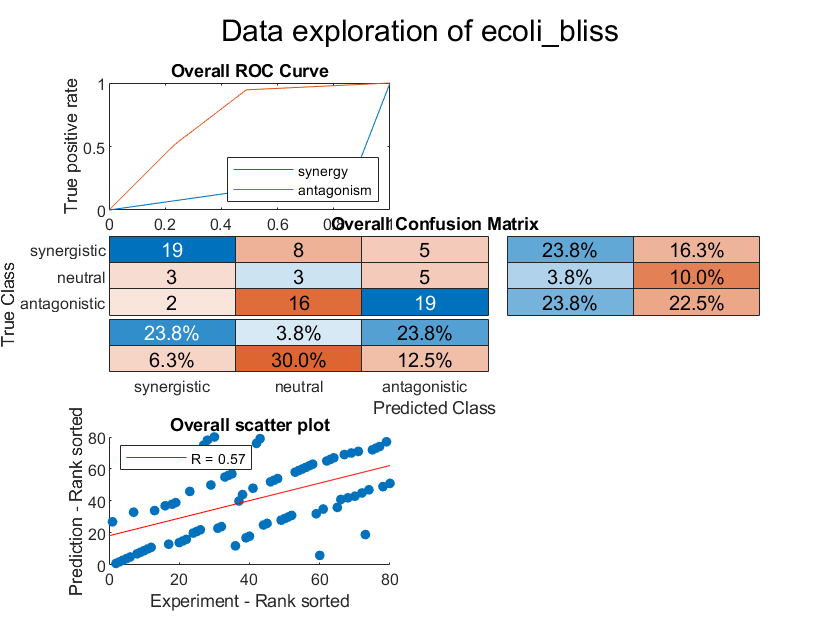

resultsTable = 5×13 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    ________________

averagesTable = 13×1 table
                                 Value 
                                _______

    Interactions                     16
    R (rank)                    0.52294
    P value                     0.12377
    Accuracy                     0.5125
    Absolute error                0.575
    Precision (synergy)         0.83143
    Recall (synergy)             0.6281
    Precision (antagonism)      0.70032
    Recall (antagonism)         0.52595
    Mean Guess Error            -0.5125
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.20894
    AUC - ROC (antagonism)      0.74834


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                        80
    R (rank)                       0.56582
    P value                     4.5187e-08
    Accuracy                        0.5125
    Absolute error                   0.575
    Precision (synergy)            0.79167
    Recall (synergy)               0.59375
    Precision (antagonism)         0.65517
    Recall (antagonism)            0.51351
    Mean Guess Error               -0.5125
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.22363
    AUC - ROC (antagonism)         0.74419


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'ecoli_bliss.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'ecoli_bw25113.xlsx';
standardize = '';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 37.077567 seconds.
Run 2
Elapsed time is 38.018062 seconds.
Run 3
Elapsed time is 42.947722 seconds.
Run 4
Elapsed time is 34.027882 seconds.
Run 5
Elapsed time is 33.307497 seconds.


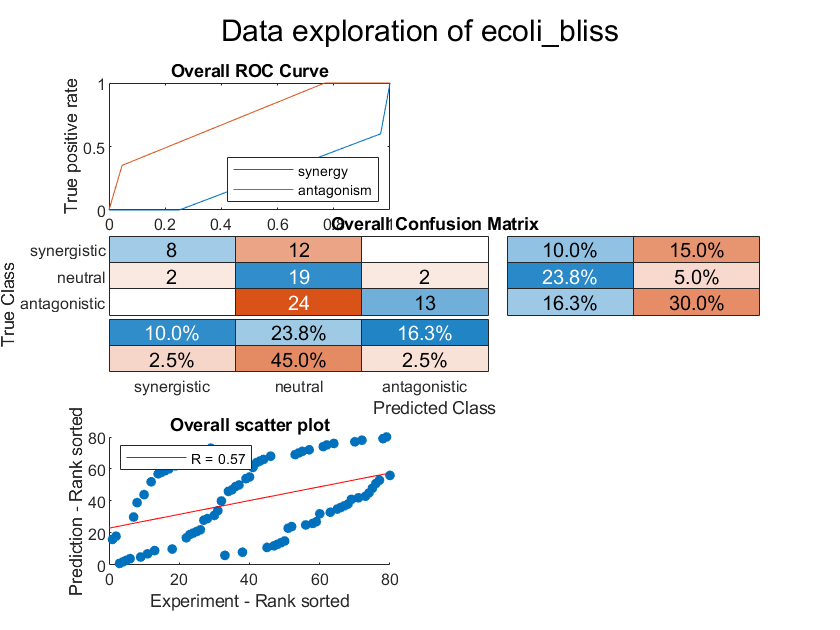

resultsTable = 5×13 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    __________________

averagesTable = 13×1 table
                                 Value  
                                ________

    Interactions                      16
    R (rank)                     0.55471
    P value                     0.054938
    Accuracy                         0.5
    Absolute error                   0.5
    Precision (synergy)          0.83333
    Recall (synergy)             0.44857
    Precision (antagonism)       0.89333
    Recall (antagonism)          0.36317
    Mean Guess Error                -0.5
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.22433
    AUC - ROC (antagonism)       0.73925


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                        80
    R (rank)                       0.56625
    P value                     4.3916e-08
    Accuracy                           0.5
    Absolute error                     0.5
    Precision (synergy)                0.8
    Recall (synergy)                   0.4
    Precision (antagonism)         0.86667
    Recall (antagonism)            0.35135
    Mean Guess Error                  -0.5
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.24167
    AUC - ROC (antagonism)         0.72784


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'ecoli_bliss.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'ecoli_iAi1.xlsx';
trainingOrthology = 'ecoli_iAi1_orthologs.xlsx';
standardize = '';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,trainingOrthology,standardize);

Run 1
Elapsed time is 47.209975 seconds.
Run 2
Elapsed time is 53.122931 seconds.
Run 3
Elapsed time is 52.212496 seconds.
Run 4
Elapsed time is 47.115853 seconds.
Run 5
Elapsed time is 46.661962 seconds.


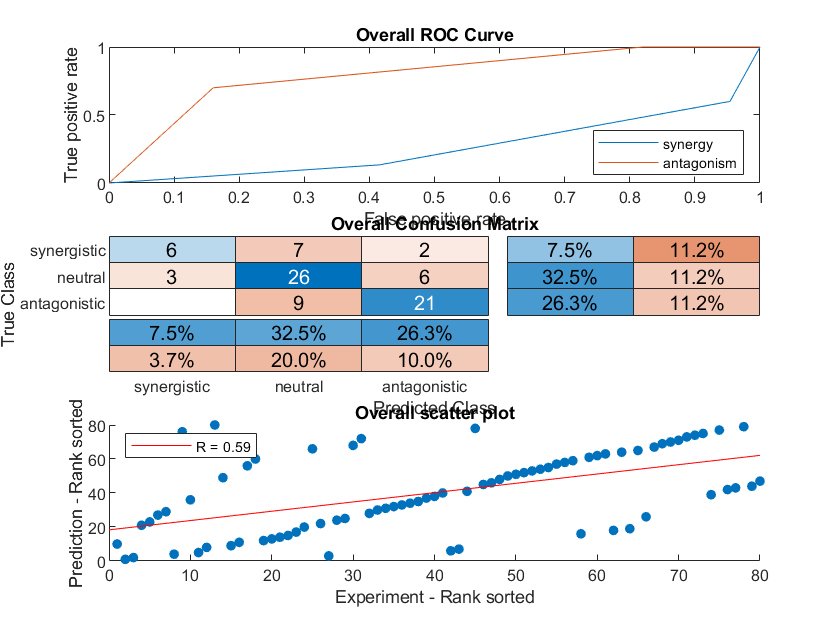

resultsTable = 5×13 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    ________________

averagesTable = 13×1 table
                                 Value  
                                ________

    Interactions                      16
    R (rank)                     0.61412
    P value                     0.024967
    Accuracy                      0.6625
    Absolute error                0.3625
    Precision (synergy)              0.8
    Recall (synergy)                 0.4
    Precision (antagonism)       0.70556
    Recall (antagonism)          0.70167
    Mean Guess Error             -0.6625
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.25696
    AUC - ROC (antagonism)       0.79579


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                        80
    R (rank)                       0.58714
    P value                     1.0381e-08
    Accuracy                        0.6625
    Absolute error                  0.3625
    Precision (synergy)            0.66667
    Recall (synergy)                   0.4
    Precision (antagonism)         0.72414
    Recall (antagonism)                0.7
    Mean Guess Error               -0.6625
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.26205
    AUC - ROC (antagonism)           0.797


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))